# Window definition methods

This livescript illustrates the various window methods of the scalographic analyses.

#### A hypothetical example of a target and rate units

Here we define the boundaries of the rate unit measure. In this example, the rate unit will be larger than the target unit (for example, the rate unit could be a syllable and the target a phone):

dt = 0.005;

TR=[];
TR.rateunit = {'sp' 's1' 's2' 's3' 's4' 's5' 's6' 'sp'}'; %sp = "silent pause"
TR.t0 = [0 0.5 0.75 1.0 1.5 1.8 2.25 2.5]'; %rate unit times
TR.t1 = [TR.t0(2:end); TR.t0(end)+0.5];
TR.dur = TR.t1-TR.t0;
TR.tmid = (TR.t0+TR.t1)/2;
TR.exclude = false(length(TR.t0),1);
TR = struct2table(TR)

TR = 8×6 table
    rateunit     t0      t1     dur     tmid     exclude
    ________    ____    ____    ____    _____    _______

     {'sp'}        0     0.5     0.5     0.25     false 
     {'s1'}      0.5    0.75    0.25    0.625     false 
     {'s2'}     0.75       1    0.25    0.875     false 
     {'s3'}        1     1.5     0.5     1.25     false 
     {'s4'}      1.5     1.8     0.3     1.65     false 
     {'s5'}      1.8    2.25    0.45    2.025     false 
     {'s6'}     2.25     2.5    0.25    2.375     false 
     {'sp'}      2.5       3     0.5     2.75     false 


Here we define a specific target unit:

%target unit
D=[];
D.t0 = 1.95;
D.t1 = 2.15;
D.tmid = (D.t0+D.t1)/2; 
D.tanch = D.tmid;
D.rateunit_t0 = TR.t0(D.t0>=TR.t0 & D.t1<TR.t1);
D.rateunit_t1 = TR.t1(D.t0>=TR.t0 & D.t1<TR.t1);
D.utt_t0 = TR.t0(2);
D.utt_t1 = TR.t1(end-1);
D = struct2table(D)

D = 1×8 table
     t0      t1     tmid    tanch    rateunit_t0    rateunit_t1    utt_t0    utt_t1
    ____    ____    ____    _____    ___________    ___________    ______    ______

    1.95    2.15    2.05    2.05         1.8           2.25         0.5       2.5  


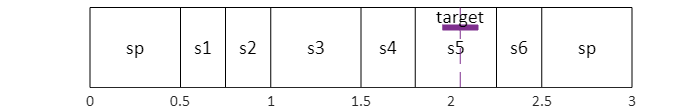

draw_intervals(TR,D)

#### define window parameters

Here are some example windows. Notice that the center and edges are specified in relative coordinates (relative to the anchorpoint of the targets.

W=[];
W.center = [-0.550 -.350 0 0 0.350 0.550]';
W.scale = [0.5 0.5 0.75 0.250 0.5 0.5]';
W.edges = W.center + W.scale .* [-1 1]/2;
W = struct2table(W)

W = 6×3 table
    center    scale         edges      
    ______    _____    ________________

    -0.55      0.5       -0.8      -0.3
    -0.35      0.5       -0.6      -0.1
        0     0.75     -0.375     0.375
        0     0.25     -0.125     0.125
     0.35      0.5        0.1       0.6
     0.55      0.5        0.3       0.8


## Basic window definition method

Simply uses the specified target window parameters

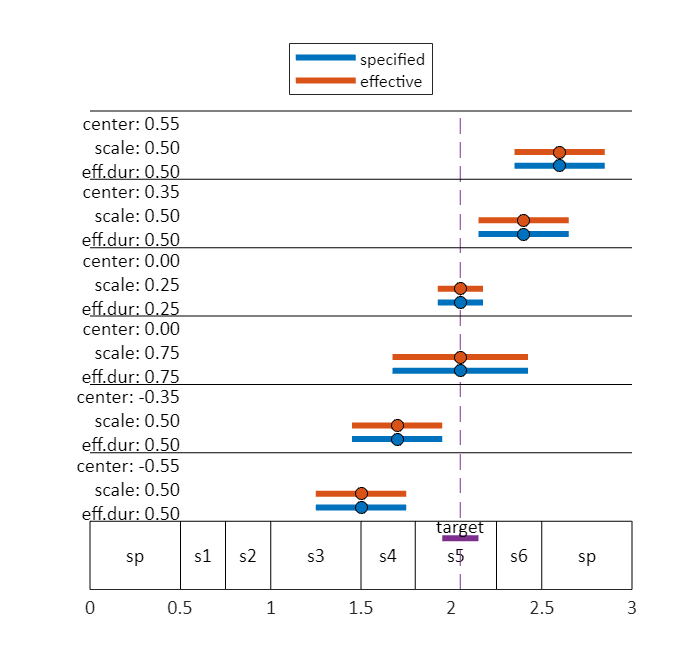

%function to calculate absolute edges
[we0,we1] = metarate_data_window_edges(D,W);
W.we0 = we0';
W.we1 = we1';

draw_intervals(TR,D,W);

## Rate-unit exclusive window

In the example above, a portion of the window overlaps the rate unit that contains the target. Thus in the basic rate-unit exclusive strategy, the effective window size (the number of frames of rate proportional duration information) that are used is less than the specified value:

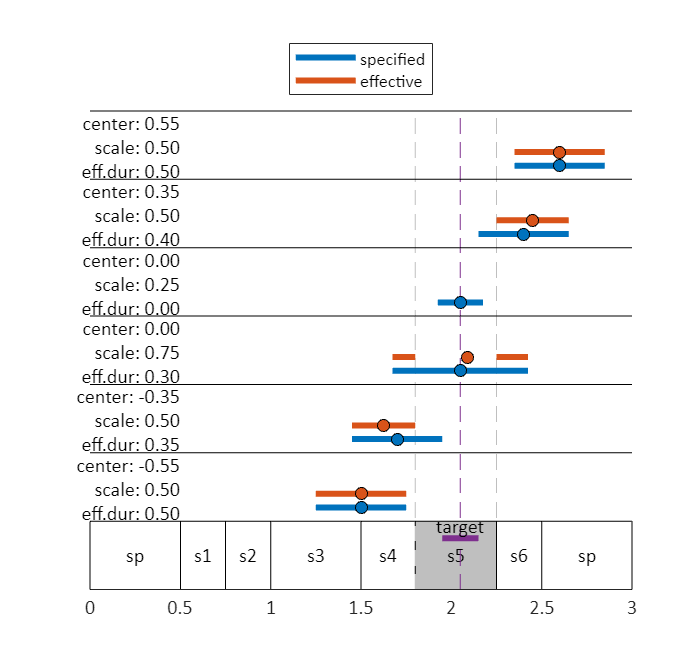

TR.exclude(TR.t0<D.tmid & TR.t1>D.tmid) = true;

draw_intervals(TR,D,W);

The problem in the above examples is that the effective window size is sometimes smaller than the specified one. This difference can be quite substantial when the containing rate-unit is large.

## Extended rate-unit exclusive window

This method compensates for the excluded duration by extending the edges of the window

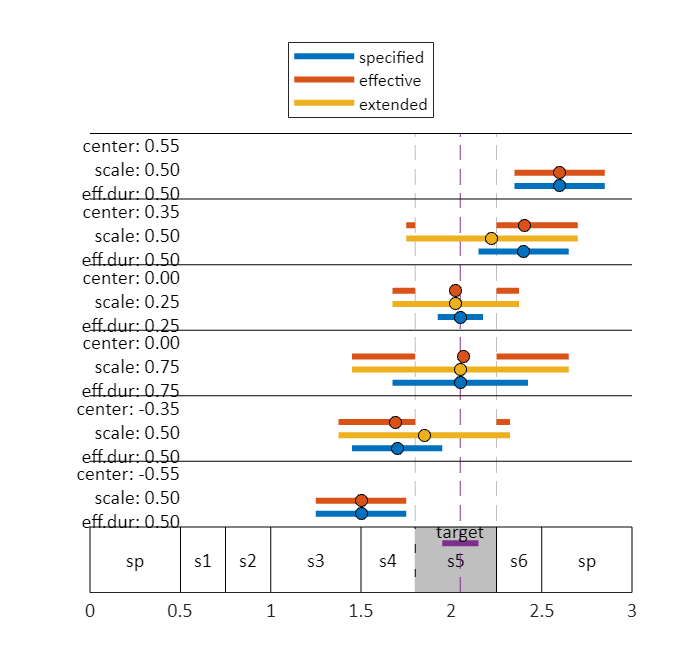

[we0,we1] = metarate_data_window_edges(D,W,'extendwin');
W.we0 = we0';
W.we1 = we1';

draw_intervals(TR,D,W);

The total duration of the effective window is now the specified window size, and there will be equal amounts of proportional duration information taken from before and after the specified window center. However, notice that the "effective center" of the effective window will differ by a small amount from the specified one. This amount depends on the amount of asymmetry in where the center of the target is located relative to the center of the rate unit.

## Adaptive window extension

Notice that the window in the previous example extends beyond the utterance. In the by-target selection strategy, this would result in the target being excluded from the analysis. To address this, the adaptive window extension method extends the window in a way that prevents it from extending beyond the utterance range:

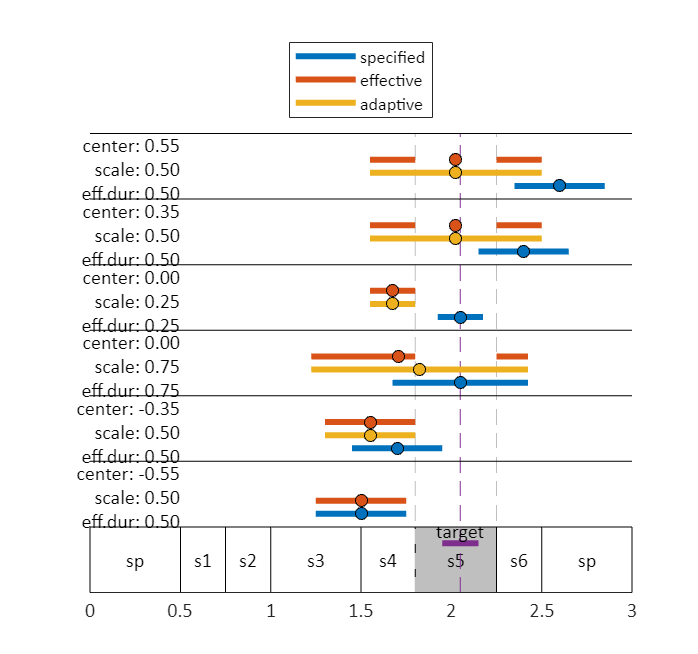

[we0,we1] = metarate_data_window_edges(D,W,'adaptivewin');

W.we0 = we0';
W.we1 = we1';
W.winmethod = repmat({'adaptivewin'},height(W),1);

draw_intervals(TR,D,W);

metarate_data_window_edges(D,W(2,:),'adaptivewin');

The total duration of the effective window is the specified window size, just as in the basic extension method. However, there will generally not be equal amounts of proportional duration information taken from before and after the specified window center, and the "effective center" of the effective window can differ by a large amount from the specified one. This make the center paramater much less meaningful, but the advantage of the method is that data from utterance edges will not be excluded.

function [] = draw_intervals(R,T,varargin)

if ~isempty(varargin)
    W = varargin{1};
    yr = [0 height(W)+1];
    figure('units','pixels','outerposition',[1 1 640 600]);
else
    yr = [0 1];
    figure('units','pixels','outerposition',[1 1 640 100]);
end

colors = [1 1 1; .75 .75 .75];
for i=1:height(R)
    fill([R.t0(i)*[1 1] R.t1(i)*[1 1]],yr(1)+[1 0 0 1],colors(R.exclude(i)+1,:),'EdgeColor','k'); hold on;
    text(R.tmid(i),0.5,R.rateunit{i},'hori','center');
    if R.exclude(i)
        plot(R.t0(i)*[1 1],yr,'--','color',colors(R.exclude(i)+1,:));
        plot(R.t1(i)*[1 1],yr,'--','color',colors(R.exclude(i)+1,:));
    end
end

colors = lines(4);

set(gca,'YColor','none','Box','off','TickDir','out','YTick',[],'TickLen',0.0001*[1 1]);
plot([T.t0 T.t1],0.75*[1 1],'-','linew',3,'color',colors(end,:)); 
plot(T.tmid*[1 1],yr,'--','color',colors(end,:));
text(T.tmid,0.75,{'target'},'hori','center','verti','bot');
ylim(yr);

effective_center = @(we)sum(mean(we,2).*diff(we,[],2))/sum(diff(we,[],2));
if nargin>2
    yoffs = 1+(0:height(W)-1);
    for i=1:height(W)
        
        
        plot([R.t0(1) R.t1(end)],1+yoffs(i)*[1 1],'k-');
        
        yo = 0.20;

        %specified 
        window_edges = T.tanch + W.edges(i,:);
        ph(1) = plot(window_edges,yo+yoffs(i)*[1 1],'-','linew',3,'color',colors(1,:));
        plot(effective_center(window_edges)*[1 1],yo+yoffs(i),'ko','MarkerFaceColor',colors(1,:));
        yo=yo+0.2;

        %extended
        if ~all(window_edges==[W.we0(i) W.we1(i)])
            window_edges = calc_effective_win([W.we0(i) W.we1(i)],R);
            window_edges = [min(window_edges(:)) max(window_edges(:))];
            ph(3) = plot(window_edges,yoffs(i)*[1 1]+yo,'-','linew',3,'color',colors(3,:));
            plot(effective_center(window_edges)*[1 1],yoffs(i)+yo,'ko','MarkerFaceColor',colors(3,:));
            yo=yo+0.2;
        end

        %effective
        window_edges = calc_effective_win([W.we0(i) W.we1(i)],R);
        if isempty(window_edges), continue; end
        for j=1:size(window_edges,1)
            ph(2) = plot(window_edges(j,:),yo+yoffs(i)*[1 1],'-','linew',3,'color',colors(2,:));
        end
        plot(effective_center(window_edges)*[1 1],yo+yoffs(i),'ko','MarkerFaceColor',colors(2,:));
                
        effective_dur = nansum(diff(window_edges,[],2));

        text(R.t0(2),1+yoffs(i),...
            sprintf('center:\t%1.2f\nscale:\t%1.2f\neff.dur:\t%1.2f\n',...
            W.center(i),W.scale(i),effective_dur),...
            'verti','top','hori','right');        
    end

    if numel(ph)==2
        legend(ph,{'specified','effective'},'location','northoutside')
    else
        if ismember('winmethod',W.Properties.VariableNames)
            legend(ph,{'specified','effective','adaptive'},'location','northoutside')
        else
            legend(ph,{'specified','effective','extended'},'location','northoutside')
        end
    end
end

end

%% effective window edges
function [weeff] =  calc_effective_win(win_edges,R)
weeff = win_edges;

if ~any(R.exclude), return; end

if (win_edges(1)<R.t0(R.exclude) && win_edges(2)>R.t1(R.exclude))
    weeff = [...
        win_edges(1) min(R.t0(R.exclude),win_edges(2));
        max(win_edges(1),R.t1(R.exclude)) win_edges(2)];

elseif win_edges(1)>=R.t0(R.exclude) &&  win_edges(2)<=R.t1(R.exclude)
    weeff = [nan nan];

elseif win_edges(1)>R.t0(R.exclude)
    weeff(1) = max(R.t1(R.exclude),win_edges(1));

elseif win_edges(2)<R.t1(R.exclude)
    weeff(2) = min(R.t0(R.exclude),win_edges(2));

end
end
